data = transpose(importdata("dataset/degradationLaser.txt"));
data

data =          0    0.4700    0.9300    2.1100    2.7200    3.5100    4.3400    4.9100    5.4800    5.9900    6.7200    7.1300    8.0000    8.9200    9.4900    9.8700   10.9400
         0    0.7100    1.2200    1.9000    2.3000    2.8700    3.7500    4.4200    4.9900    5.5100    6.0700    6.6400    7.1600    7.7800    8.4200    8.9100    9.2800
         0    0.7100    1.1700    1.7300    1.9900    2.5300    2.9700    3.3000    3.9400    4.1600    4.4500    4.8900    5.2700    5.6900    6.0200    6.4500    6.8800
         0    0.3600    0.6200    1.3600    1.9500    2.3000    2.9500    3.3900    3.7900    4.1100    4.5000    4.7200    4.9800    5.2800    5.6100    5.9500    6.1400
         0    0.2700    0.6100    1.1100    1.7700    2.0600    2.5800    2.9900    3.3800    4.0500    4.6300    5.2400    5.6200    6.0400    6.3200    7.1000    7.5900
         0    0.3600    1.3900    1.9500    2.8600    3.4600    3.8100    4.5300    5.3500    5.9200    6.7100    7.7000    8.6100    9.15

tdata0=0:250:4000

tdata0 =            0         250         500         750        1000        1250        1500        1750        2000        2250        2500        2750        3000        3250        3500        3750        4000


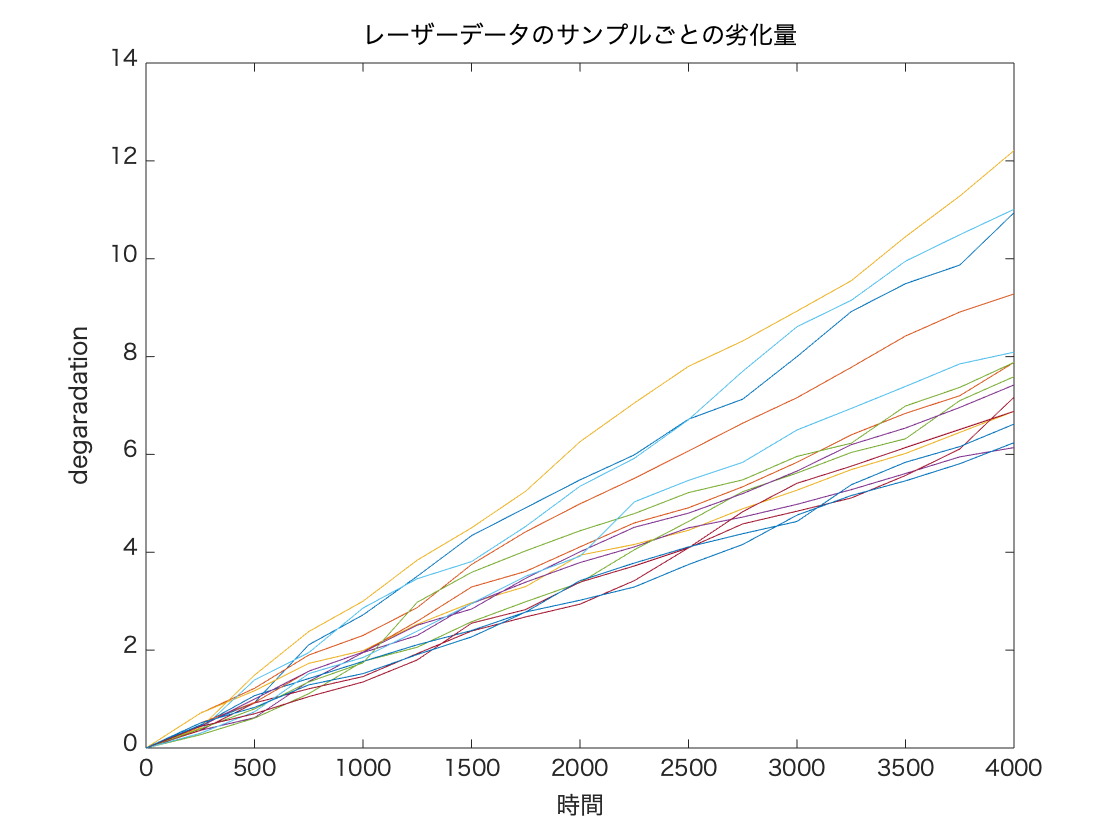

plot(tdata0,data(1,:))
hold on
for i=2:15
    plot(tdata0,data(i,:))
end
hold off

xlim([0 4000])
ylim([0.0 14.0])
title('レーザーデータのサンプルごとの劣化量')
xlabel('時間')
ylabel('degaradation')

x = importdata("dataset/jumpsizedata.txt")

x =     0.4700    0.7100    0.7100    0.3600    0.2700    0.3600    0.3600    0.4600    0.5100    0.4100    0.4400    0.3900    0.3000    0.4400    0.5100
    0.4600    0.5100    0.4600    0.2600    0.3400    1.0300    0.5600    0.6100    0.4200    1.0800    0.5600    0.4100    0.4400    0.2600    0.3200
    1.1800    0.6800    0.5600    0.7400    0.5000    0.5600    0.2900    0.3500    0.6400    0.8900    0.5700    0.5500    0.7800    0.3500    0.4600
    0.6100    0.4000    0.2600    0.5900    0.6600    0.9100    0.2500    0.3500    0.3900    0.6200    0.3900    0.3900    0.3300    0.3000    0.2300
    0.7900    0.5700    0.5400    0.3500    0.2900    0.6000    0.4700    0.3400    0.6300    0.8400    0.5500    1.2400    0.5400    0.4500    0.3900
    0.8300    0.8800    0.4400    0.6500    0.5200    0.3500    0.4600    0.2900    0.7000    0.6600    0.3300    0.6100    0.5600    0.7500    0.3600
    0.5700    0.6700    0.3300    0.4400    0.4100    0.7200    0.2900    0.3800    0.3200

mulist = zeros (1, length (x));
lambdalist = zeros (1, length (x));
for i=1: length (x)
mlelist = mle(x(i ,:) ,'distribution','InverseGaussian');
mulist (i) = mlelist (1);
lambdalist (i) = mlelist (2) ;
end

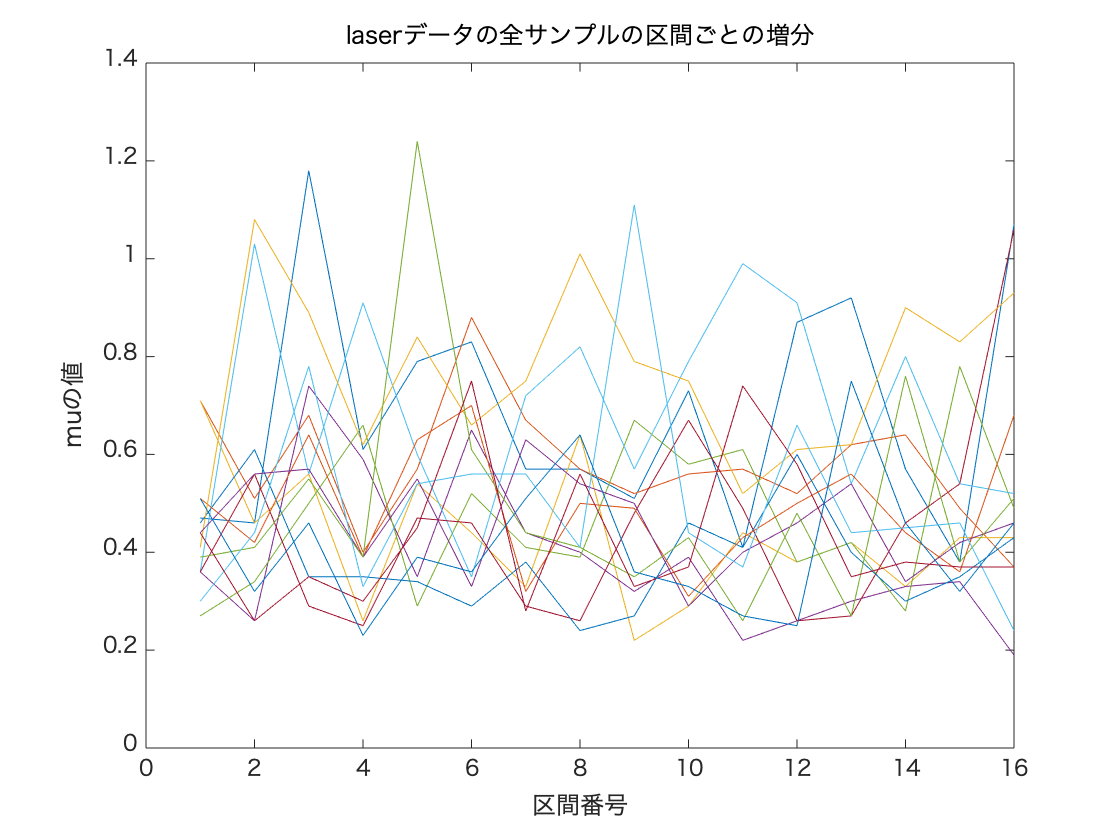

laserjump = transpose(x);
laserinterval = 1:1:16;
plot(laserinterval,laserjump(1,:))
hold on
for i=2:15
    plot(laserinterval,laserjump(i,:))
end
hold off
xlabel('区間番号')
ylabel('muの値')
title('laserデータの全サンプルの区間ごとの増分')

newmulist = cumsum([0 mulist])

newmulist =          0    0.4467    0.9613    1.5680    2.0133    2.5860    3.1453    3.6320    4.1627    4.6620    5.1547    5.6300    6.1447    6.6393    7.1353    7.6013    8.1487


newlambdalist = cumsum([0 lambdalist])

newlambdalist =          0    6.3107    9.2391   13.6603   16.3947   20.3837   25.0029   29.5871   33.1846   35.9516   39.9876   43.0261   46.1614   49.9641   53.5936   59.3852   61.5985


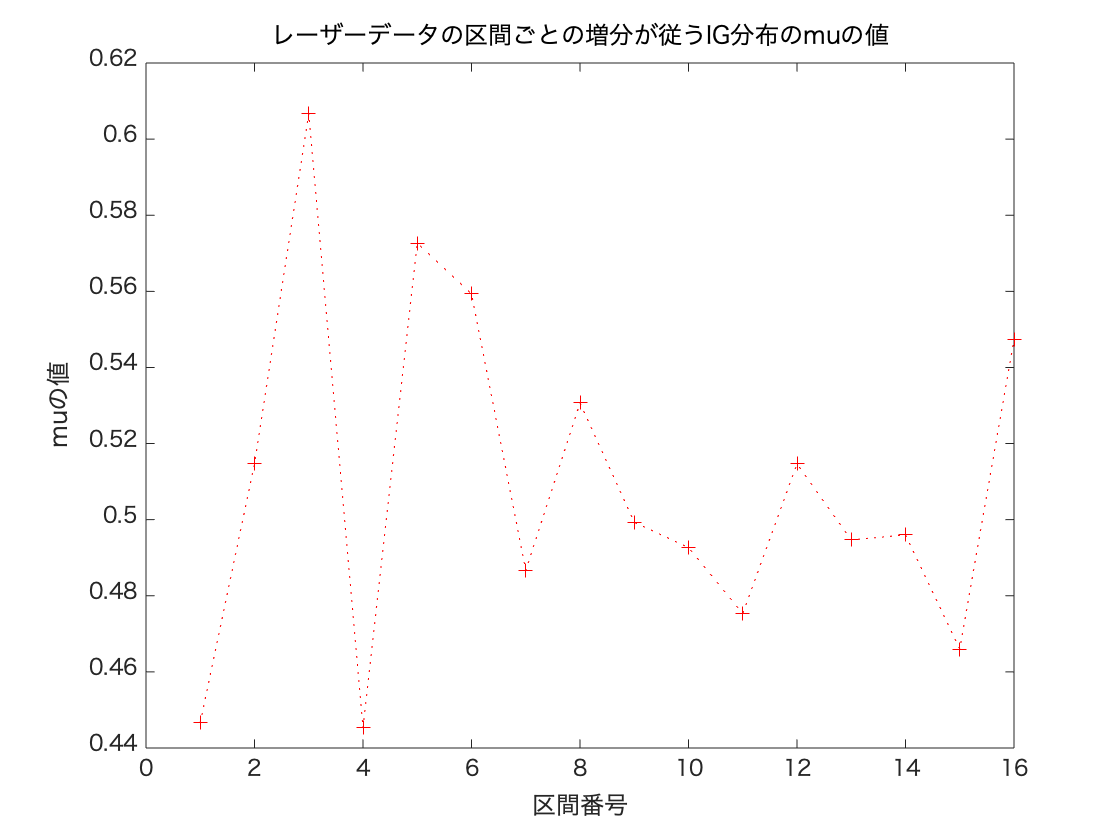

laserinterval = 1:1:16;
plot(laserinterval,mulist,"r:+")

title('レーザーデータの区間ごとの増分が従うIG分布のmuの値')
xlabel('区間番号')
ylabel('muの値')

# クラックデータ２のプロット

%crackdata2のインポート
crack2jump = importdata("dataset/crackdata2.txt")

crack2jump =     0.0500    0.0500    0.0500    0.0700    0.0700    0.0800    0.0800    0.1300    0.1600       NaN       NaN       NaN
    0.0400    0.0400    0.0500    0.0500    0.0600    0.0700    0.0700    0.0900    0.1000    0.1300       NaN       NaN
    0.0400    0.0400    0.0500    0.0500    0.0500    0.0600    0.0700    0.0900    0.1100    0.1200    0.1900       NaN
    0.0400    0.0400    0.0500    0.0400    0.0500    0.0700    0.0600    0.0900    0.0900    0.1200    0.1800       NaN
    0.0400    0.0400    0.0500    0.0400    0.0500    0.0700    0.0500    0.1000    0.0900    0.1200    0.1600       NaN
    0.0400    0.0400    0.0500    0.0400    0.0500    0.0600    0.0500    0.1000    0.0800    0.1000    0.1700       NaN
    0.0400    0.0400    0.0400    0.0500    0.0400    0.0600    0.0600    0.0900    0.0900    0.1100    0.1400       NaN
    0.0300    0.0400    0.0300    0.0600    0.0500    0.0600    0.0600    0.0700    0.0900    0.1000    0.1300       NaN
    0.0200    0.050

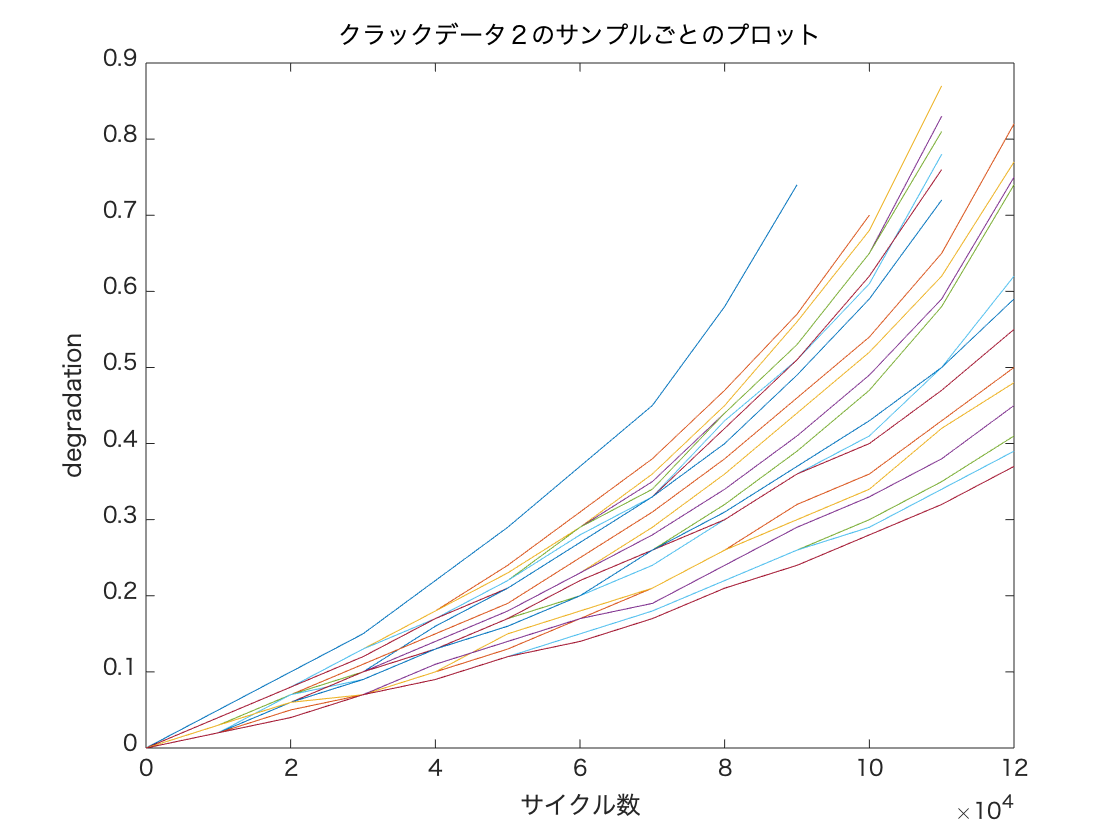

%全サンプルのプロット
z = transpose(zeros(1,21));
crack2time = 0:10000:120000;
crack2cum = cumsum([z crack2jump],2);
plot(crack2time,crack2cum(1,:))
hold on
for i=2:21
    plot(crack2time,crack2cum(i,:))
end
hold off

title('クラックデータ２のサンプルごとのプロット')
xlabel('サイクル数')
ylabel('degradation')

crack2mulist = zeros (1,12);
crack2lambdalist = zeros (1,12);
for i=1:12
crack2mlelist = mle(crack2jump(:,i) ,'distribution','InverseGaussian');
crack2mulist (i) = crack2mlelist (1);
crack2lambdalist (i) = crack2mlelist (2) ;
end
crack2mulist

crack2mulist =     0.0295    0.0357    0.0362    0.0390    0.0419    0.0490    0.0500    0.0686    0.0738    0.0750    0.1032    0.0992


crack2interval = 1:1:12

crack2interval =      1     2     3     4     5     6     7     8     9    10    11    12


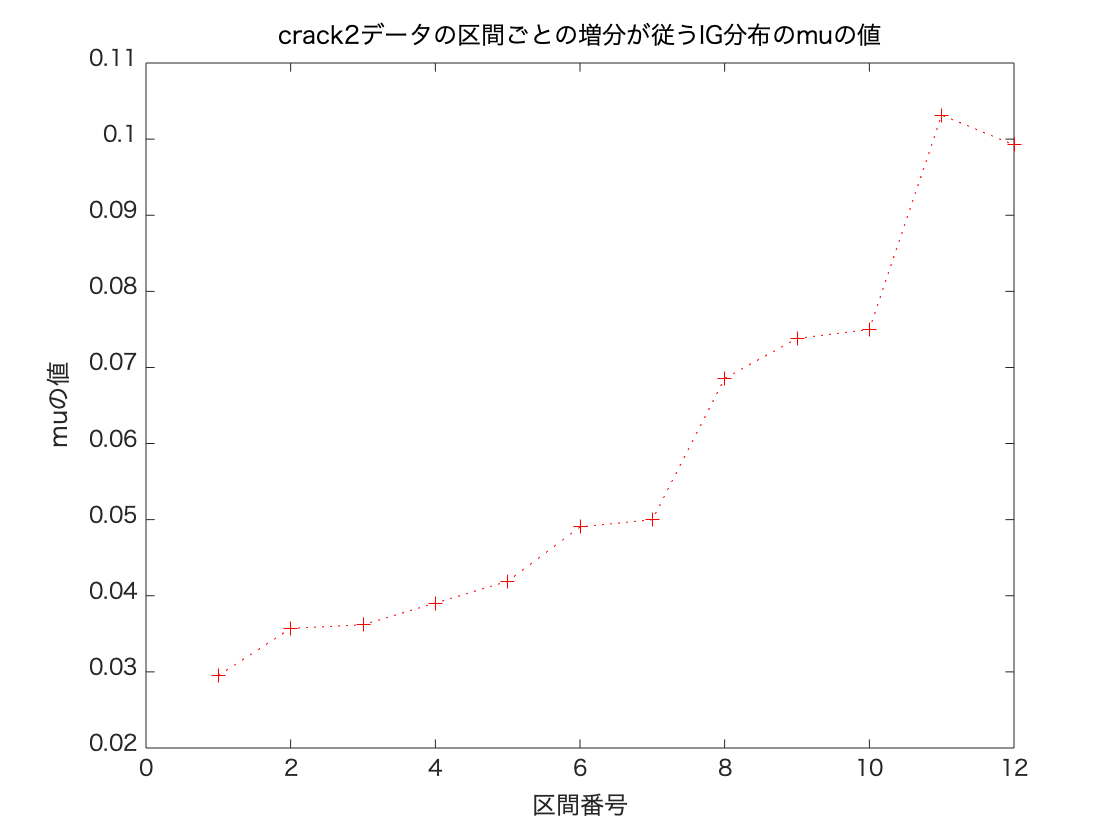

plot(crack2interval, crack2mulist,"r:+")

xlabel('区間番号')
ylabel('muの値')
title('crack2データの区間ごとの増分が従うIG分布のmuの値')

%muの累積グラフ
crack2cummulist = cumsum([0 crack2mulist])

crack2cummulist =          0    0.0295    0.0652    0.1014    0.1405    0.1824    0.2314    0.2814    0.3500    0.4238    0.4988    0.6020    0.7012


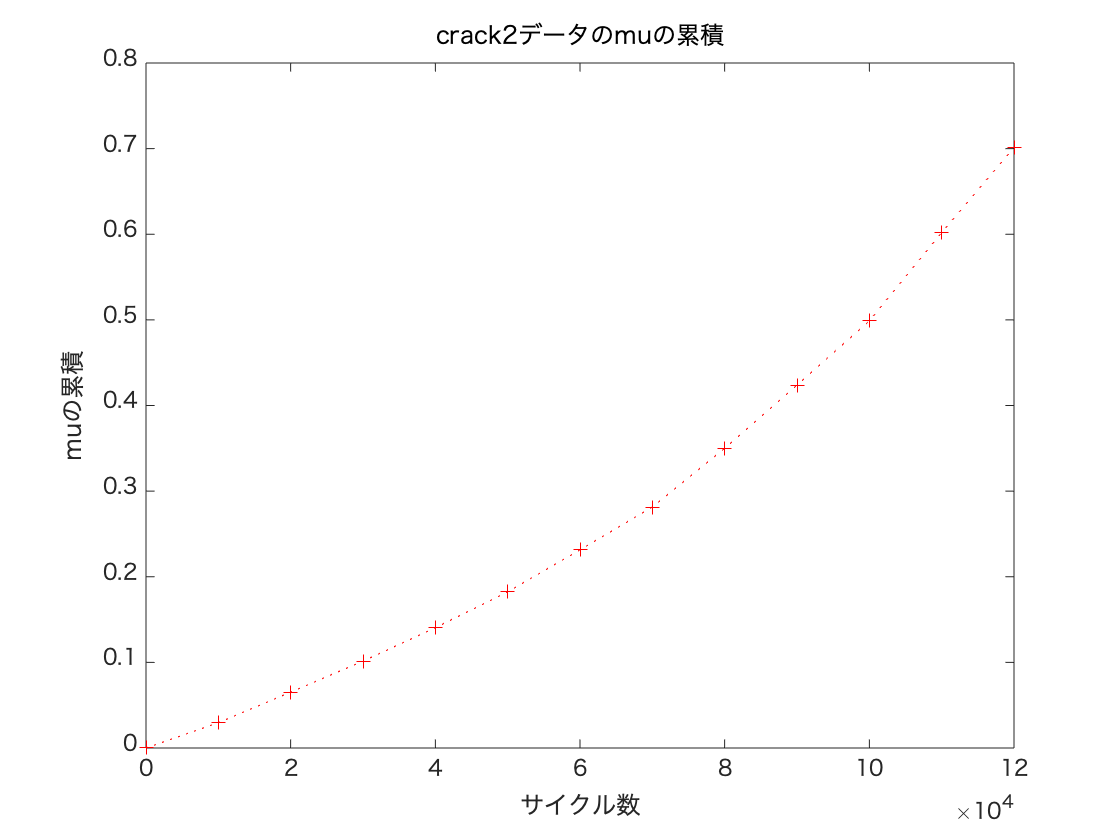

plot(crack2time,crack2cummulist,"r:+")

title('crack2データのmuの累積')
xlabel('サイクル数')
ylabel('muの累積')

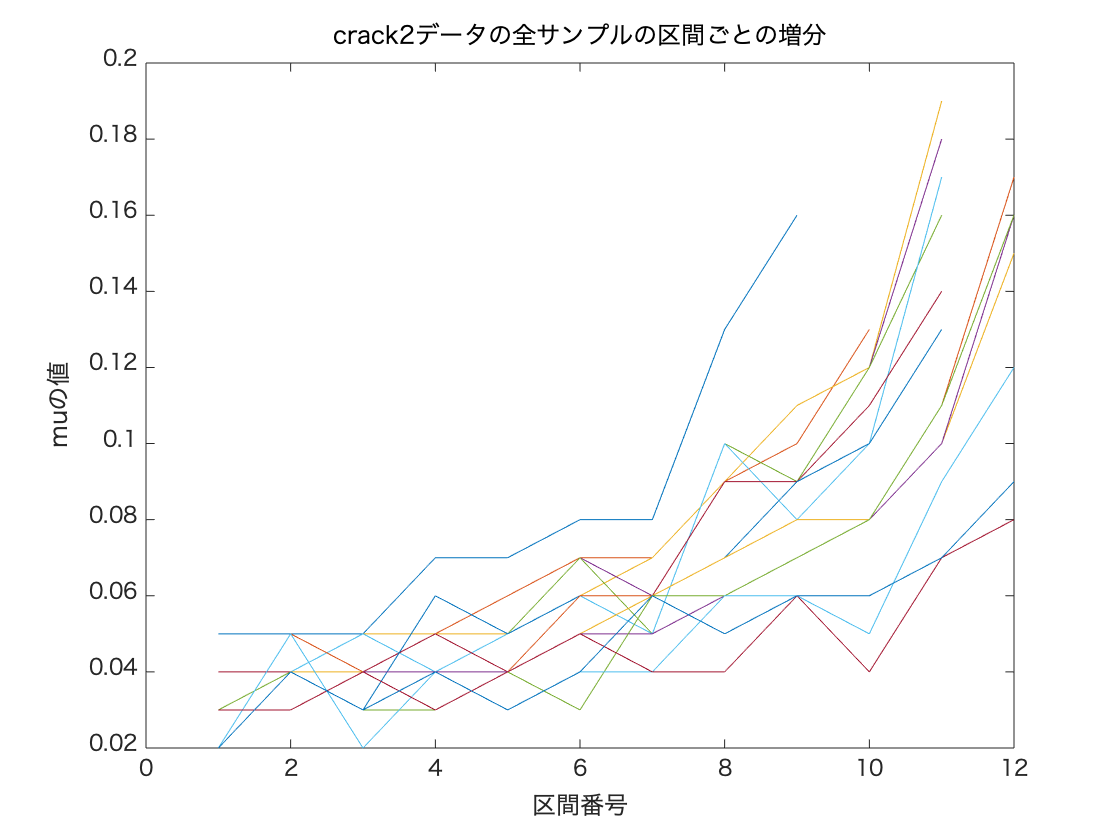

plot(crack2interval,crack2jump(1,:))
hold on
for i=2:15
    plot(crack2interval,crack2jump(i,:))
end
hold off
xlabel('区間番号')
ylabel('muの値')
title('crack2データの全サンプルの区間ごとの増分')

# クラックデータ１のプロット

%crackdata1のインポート
crack1jump = importdata("dataset/jumpcrackWu.txt")

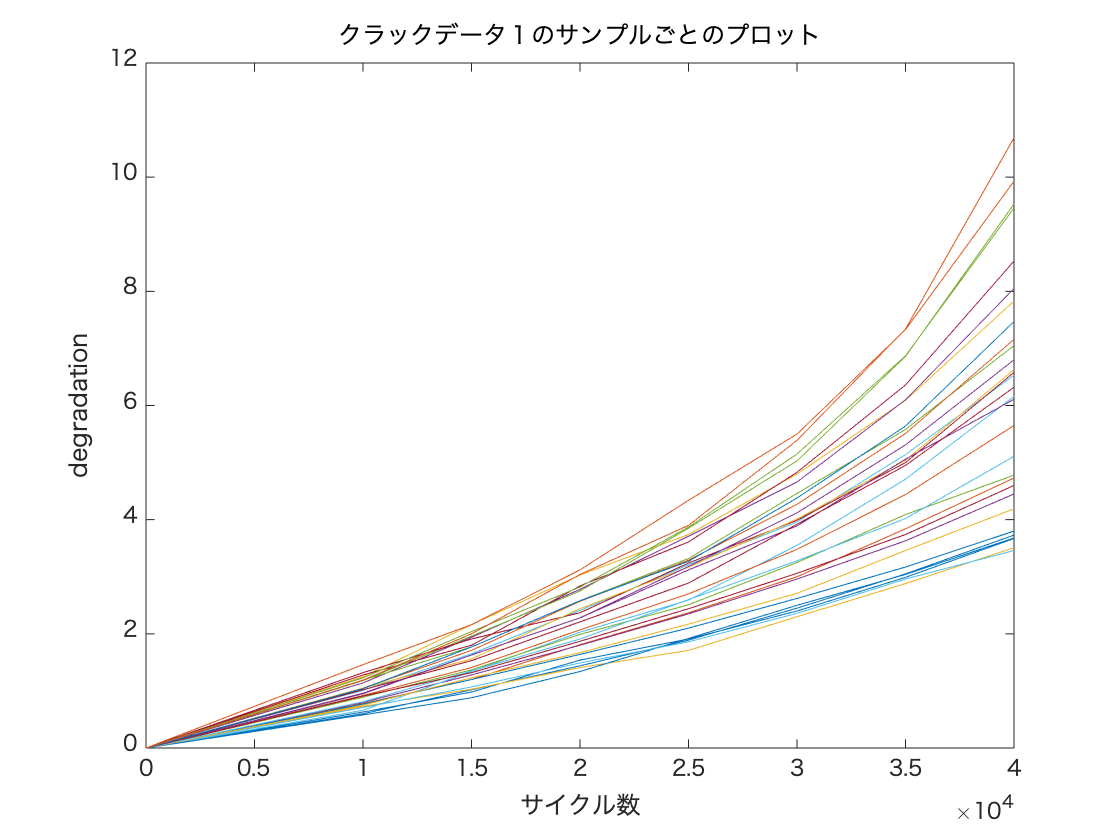

%全サンプルのプロット
z = transpose(zeros(1,30));
crack1time = [0 10000:5000:40000];
crack1cum = cumsum([z crack1jump],2);
plot(crack1time,crack1cum(1,:))
hold on
for i=2:30
    plot(crack1time,crack1cum(i,:))
end
hold off

title('クラックデータ１のサンプルごとのプロット')
xlabel('サイクル数')
ylabel('degradation')

%増分のグラフ
crack1mulist = zeros (1,7);
crack1lambdalist = zeros (1,7);
for i=1:7
crack1mlelist = mle(crack1jump(:,i) ,'distribution','InverseGaussian');
crack1mulist (i) = crack1mlelist (1);
crack1lambdalist (i) = crack1mlelist (2) ;
end
crack1mulist

crack1mulist =     0.9620    0.5680    0.6737    0.6907    0.8483    1.0640    1.3997


crack1interval = 1:1:7

crack1interval =      1     2     3     4     5     6     7


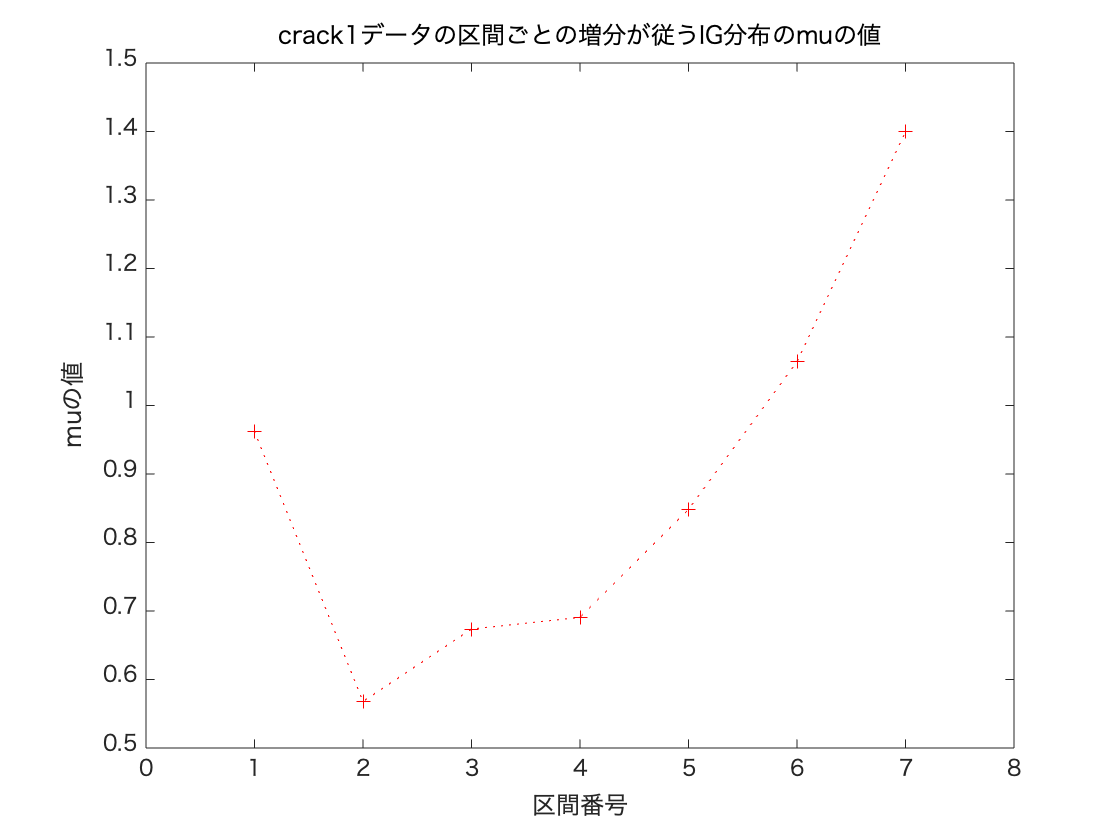

plot(crack1interval, crack1mulist,"r:+")

xlabel('区間番号')
ylabel('muの値')
title('crack1データの区間ごとの増分が従うIG分布のmuの値')

xlim([0.00 8.00])
ylim([0.500 1.500])

%最初の区間だけ増分が多くなっているのは、最初だけ10000サイクルで、そのあとは全て5000サイクルだから

%muの累積グラフ
crack1cummulist = cumsum([0 crack1mulist])

crack1cummulist =          0    0.9620    1.5300    2.2037    2.8943    3.7427    4.8067    6.2063


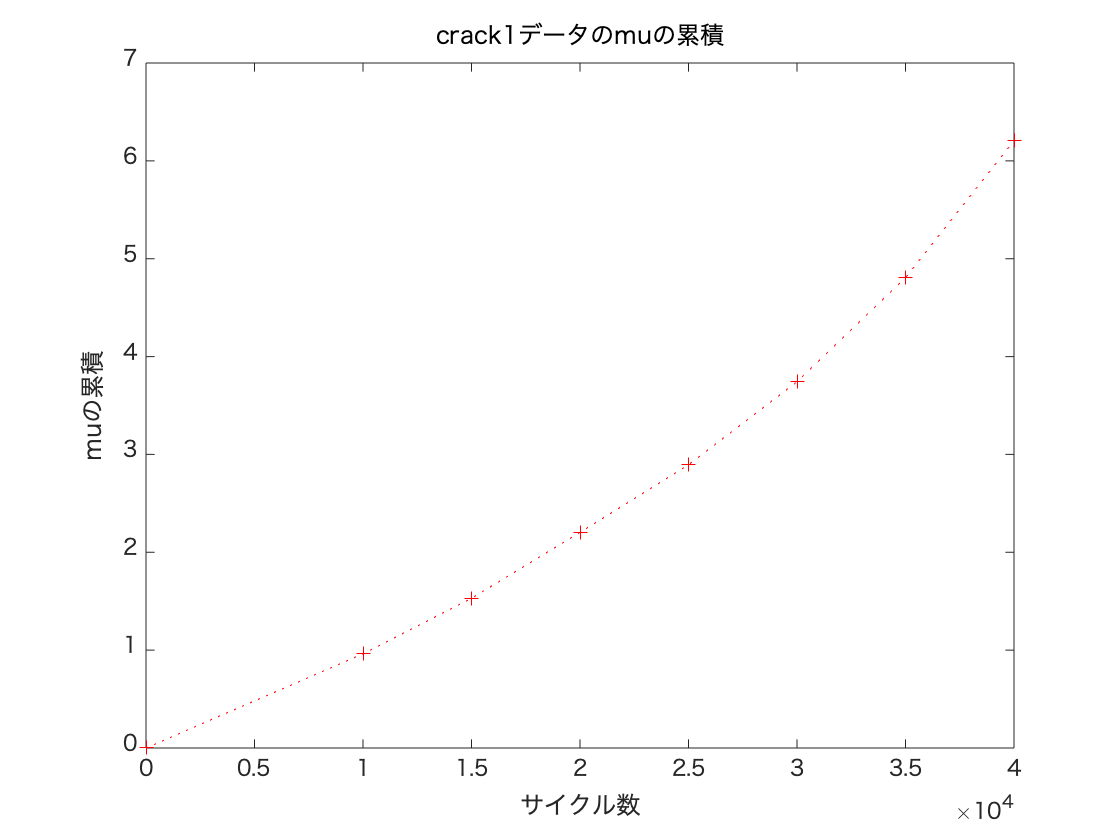

plot(crack1time,crack1cummulist,"r:+")

title('crack1データのmuの累積')
xlabel('サイクル数')
ylabel('muの累積')

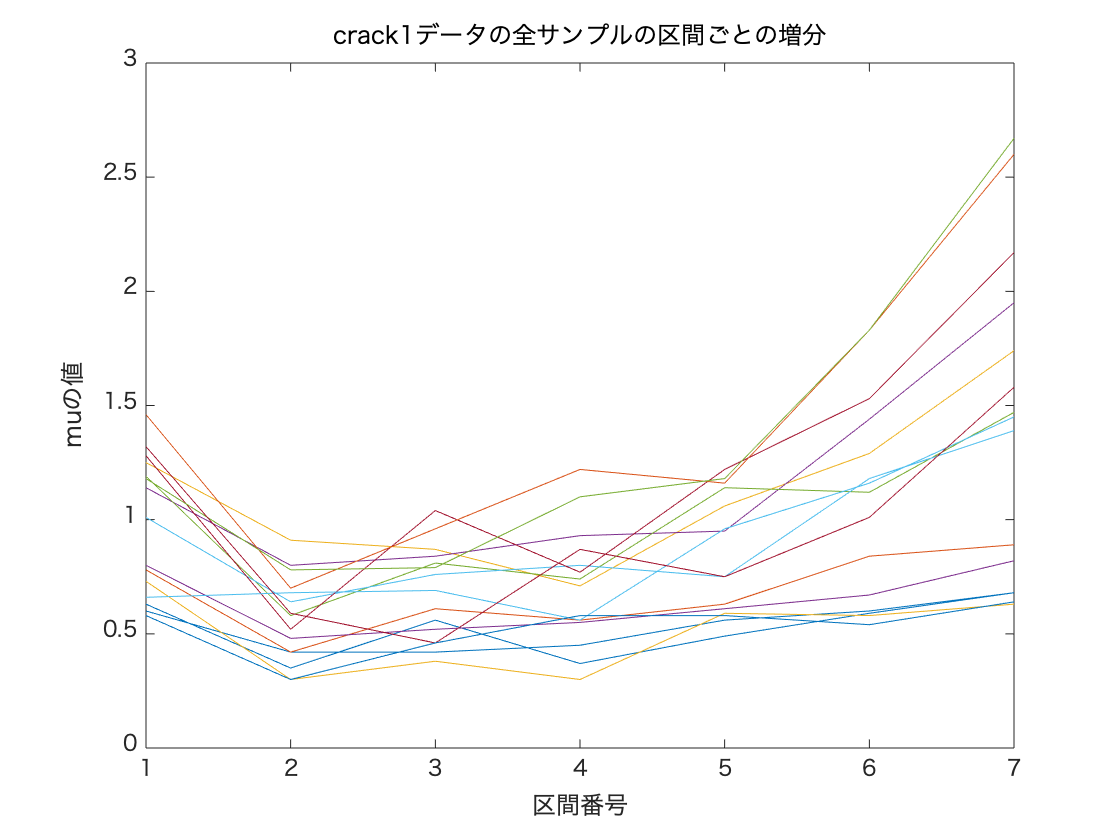

%増分の全サンプルプロット
plot(crack1interval,crack1jump(1,:))
hold on
for i=2:15
    plot(crack1interval,crack1jump(i,:))
end
hold off
xlabel('区間番号')
ylabel('muの値')
title('crack1データの全サンプルの区間ごとの増分')

# クラックデータ３のプロット

%crackdata3のインポート
crack3jump = importdata("../dataset/crackdata3.txt")

crack3jump =     0.0100    0.0200    0.0250    0.0520    0.0580    0.0180    0.0170    0.0600    0.0420
    0.0900    0.0710    0.0110    0.0750    0.0120    0.0220    0.0900    0.0300    0.0280
    0.0100    0.0500    0.0210    0.0370    0.0240    0.0160    0.0110    0.0630    0.0300
    0.0160    0.0600    0.0110    0.0170    0.0230    0.0710    0.0100    0.0100    0.0400
    0.0360    0.0600    0.0800    0.0280    0.0380    0.0390    0.0440    0.0900    0.0800
    0.0140    0.0880    0.0100    0.0820    0.0830    0.0120    0.0160    0.0300    0.0560
    0.0370    0.0270    0.0140    0.0180    0.0280    0.0400    0.0700    0.0200    0.0720
    0.0350    0.0510    0.0190    0.0690    0.0930    0.0100    0.0700    0.0140    0.0230
    0.0670    0.0810    0.0130    0.0120    0.0110    0.0340    0.0110    0.0100    0.0460
    0.0250    0.0270    0.0120    0.0120    0.0750    0.0360    0.0180    0.0170    0.0400


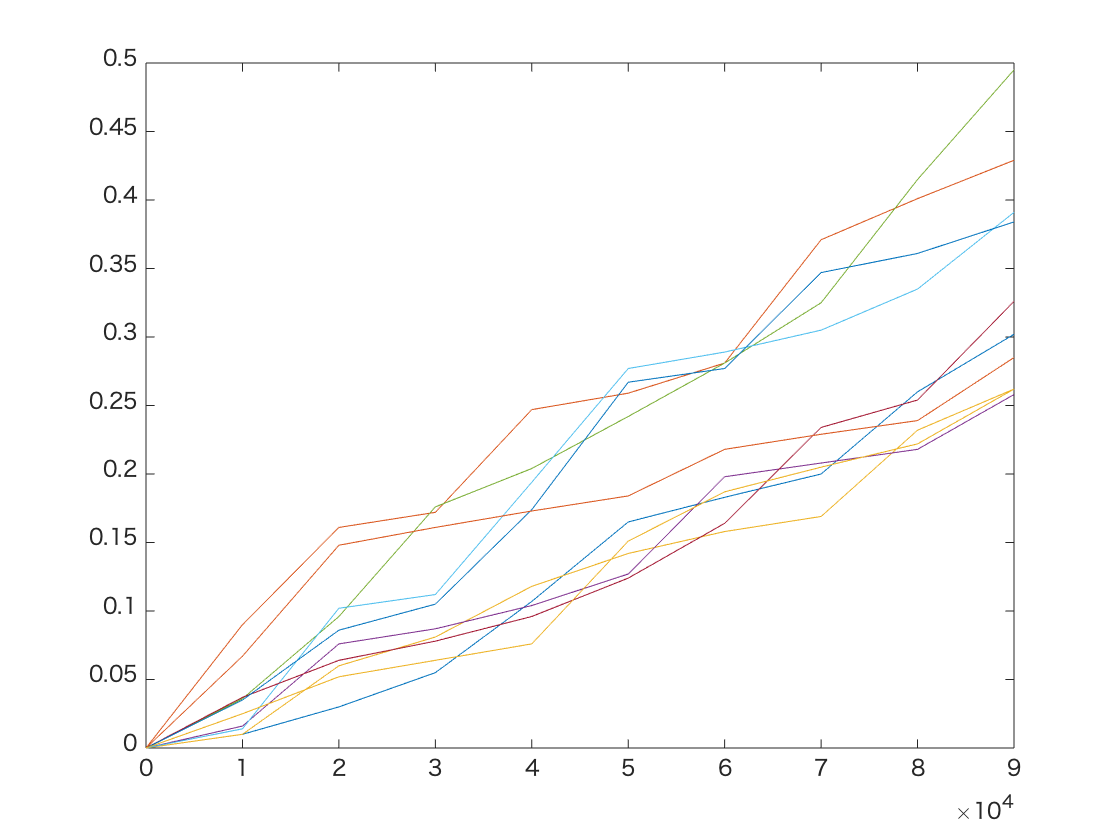

%全サンプルのプロット
z = transpose(zeros(1,10));
crack3time = 0:10000:90000;
crack3cum = cumsum([z crack3jump],2);
plot(crack3time,crack3cum(1,:))
hold on
for i=2:10
    plot(crack3time,crack3cum(i,:))
end
hold off

%増分のグラフ
crack3mulist = zeros (1,9);
crack3lambdalist = zeros (1,9);
for i=1:9
crack3mlelist = mle(crack3jump(:,i) ,'distribution','InverseGaussian');
crack3mulist (i) = crack3mlelist (1);
crack3lambdalist (i) = crack3mlelist (2) ;
end
crack3mulist

crack3mulist =     0.0340    0.0535    0.0216    0.0402    0.0445    0.0298    0.0357    0.0344    0.0457


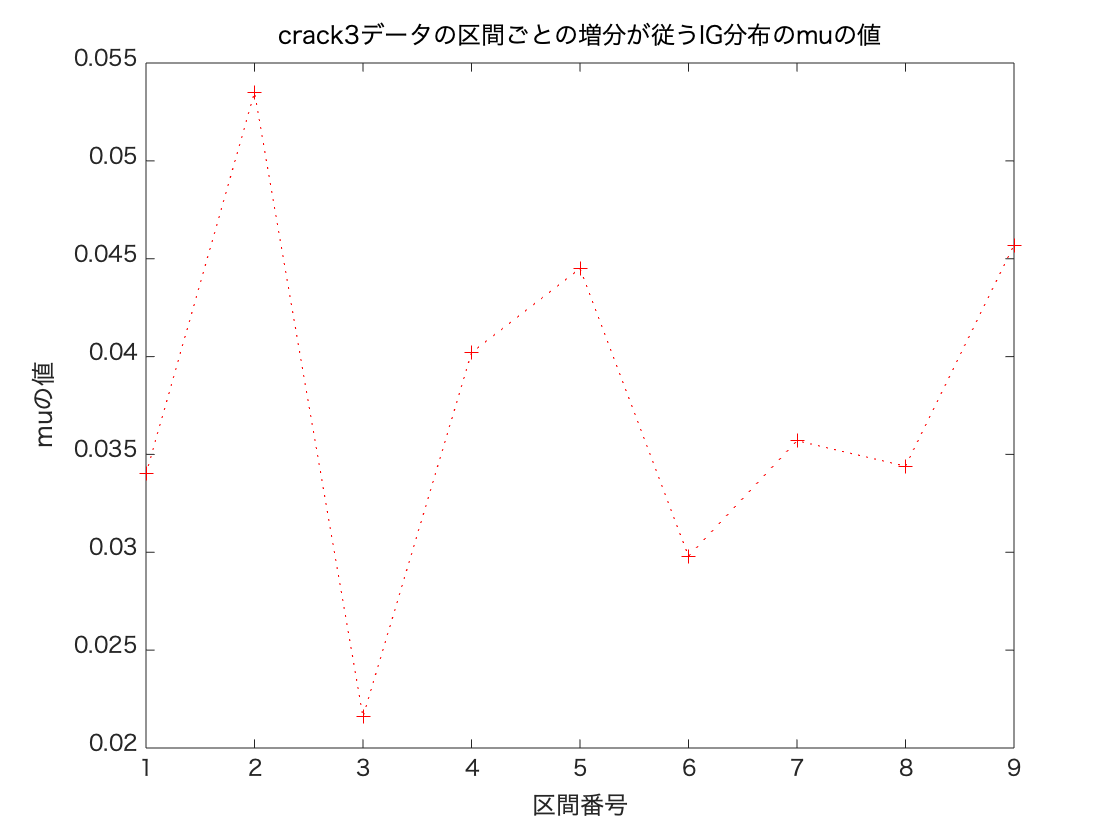

crack3interval = 1:1:9;
plot(crack3interval, crack3mulist,"r:+")

xlabel('区間番号')
ylabel('muの値')
title('crack3データの区間ごとの増分が従うIG分布のmuの値')

%muの累積グラフ
crack3cummulist = cumsum([0 crack3mulist])

crack3cummulist =          0    0.0340    0.0875    0.1091    0.1493    0.1938    0.2236    0.2593    0.2937    0.3394


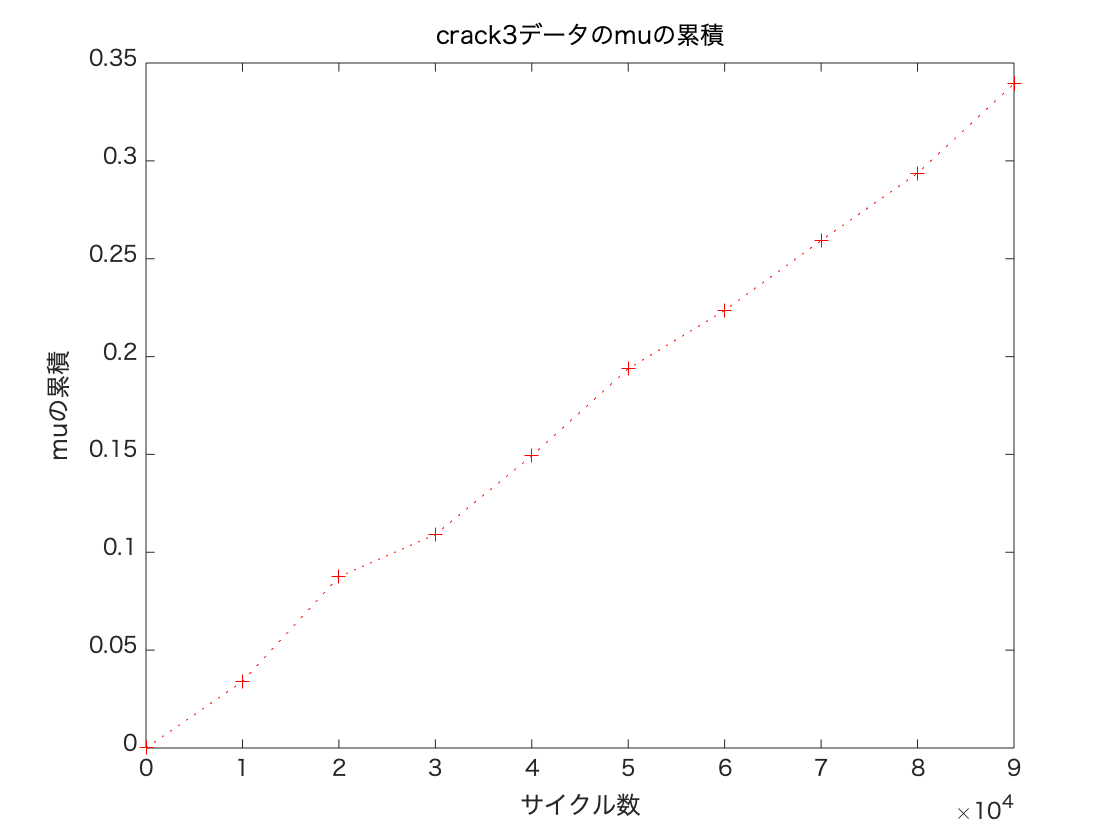

plot(crack3time,crack3cummulist,"r:+")

title('crack3データのmuの累積')
xlabel('サイクル数')
ylabel('muの累積')

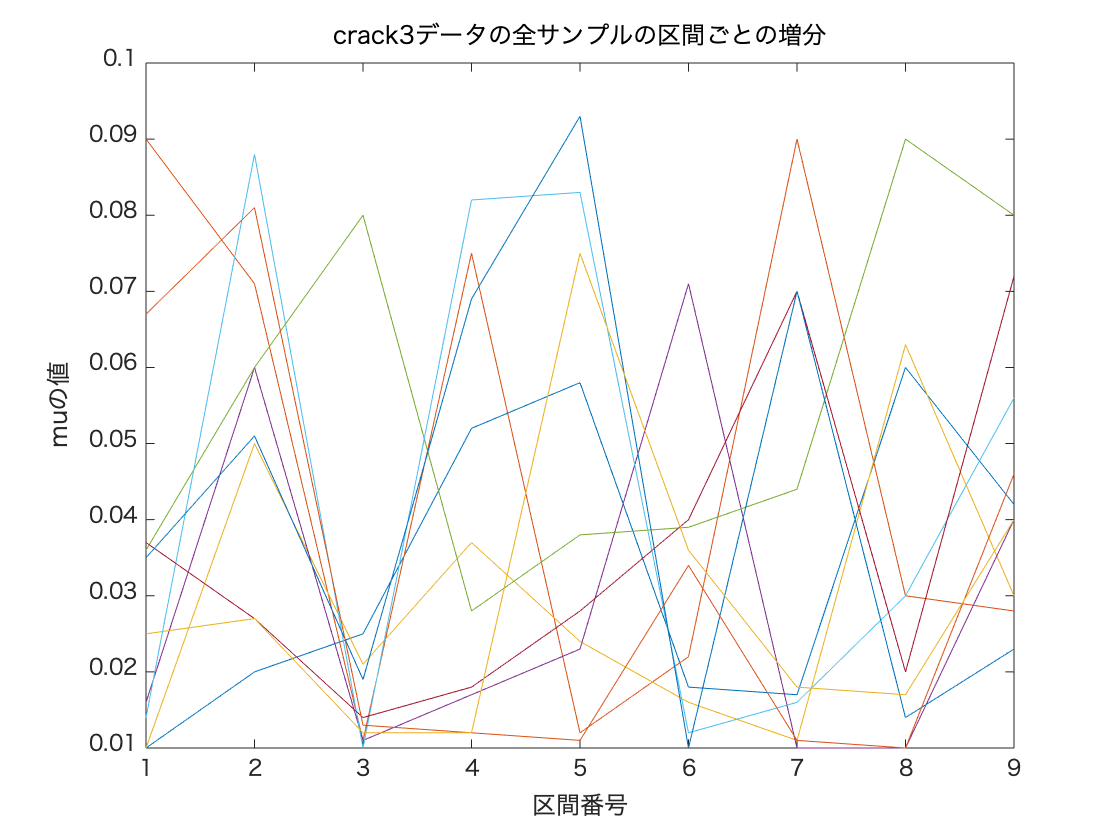

%増分の全サンプルプロット
plot(crack3interval,crack3jump(1,:))
hold on
for i=2:10
    plot(crack3interval,crack3jump(i,:))
end
hold off
xlabel('区間番号')
ylabel('muの値')
title('crack3データの全サンプルの区間ごとの増分')